# PROYECTO I

# Procesamiento Señales de Audio

**A.** Ambiente de programación: MATLAB 

**B.** Señal de entrada análoga: Voz y música


%Entrada de Voz y música
[archivo,ruta]=uigetfile('*.mp3','Cargar Audio-MP3');
archivo

archivo = 0

ruta

ruta = 0

%audio(archivo)
if archivo==0
 return;
else
 dat_archivo=strcat(ruta,archivo);

A = importdata(dat_archivo);

[a, fs]=audioread(dat_archivo);
audioinfo(dat_archivo)
% plot(a(1:100000,1))
B1 = flip(a(:,1));
B2 = flip(a(:,2));
B =[B1,B2];
end

% reproductor = audioplayer(a,fs)
Mono= (a(:,1)+a(:,2))/2

reproductor = audioplayer(B,fs)
play(reproductor);
pause(40)
stop(reproductor)

% importdata()
plot(a(:,1))
plot(B(:,1))


Mono= (a(:,1)+a(:,2))/2

**C.** Adquisición: Micrófono y Tarjeta de audio del PC. 

%Entrada de  VOZ
grabar= audiorecorder(8000,8,1,1);
text_Caja={ 'Segundos grabación:',};
title_caja='Grabación';
num_lines = 1;
defaultans = {'2'};
caja =inputdlg(text_Caja,title_caja,num_lines,defaultans);
T_record=str2num(caja{1});
recordblocking(grabar,T_record);
% play(grabar)
Data_audio = getaudiodata(grabar,"uint8")
reproductor = audioplayer(Data_audio,8000,8)
play(reproductor);


myVoice = audiorecorder;

disp('Start speaking.');
recordblocking(myVoice, 5);
disp('End of recording. Playing back ...');

play(myVoice);

**D.** Funciones de Procesamiento 

- Convolución sistema FIR: $y\left(n\right)=\sum_{k=0}^n x\left(n-k\right)h\left(k\right)$ 

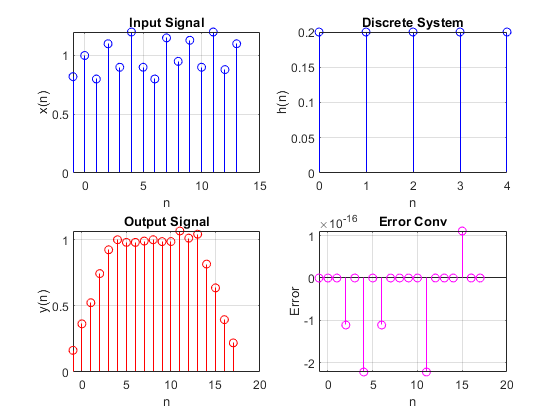

clc; clearvars; close all;
% Entrada h(n) y x(n)
dlg_title = 'Convolución';
prompt = { 'Entre h(n):','Entre n inicial:', 'Entre x(n):','Entre n inicial:'};
num_lines = 1;
defaultans = {'1/5 1/5 1/5 1/5 1/5 ', '0', ...
 '0.82  1  0.8  1.1  0.9   1.2  0.9  0.8  1.15  0.95  1.13  0.9  1.2  0.88  1.1', '-1'};
answer = inputdlg(prompt,dlg_title,num_lines,defaultans);

% Obtención de h(n) 
h=str2num(answer{1});
nhi=str2num(answer{2});   %instante inicio
lh=length(h);   %longitud vector h
nhf=lh+nhi-1;      %instante final

% Obtención de x(n) 
x=str2num(answer{3});
nxi=str2num(answer{4});
lx=length(x);
nxf=lx+nxi-1;

% Datos de salida y(n)
nyi=nhi+nxi;  % Instante inicio
nyf=nhf+nxf;  % Instante final

% Calculo de la convolución : y(n) = suma_k [x(k) h(n-k)]
y=zeros(1,lh+lx-1);
i=0;
for  n=nyi:nyf
   i=i+1;  
   temp=0; 
   for k= nxi: nxf
       kx=k-nxi+1; %ajuste del indice de x(n) para evitar salir rango de Matlab
       ind= n-k;
       if  ind >= nhi && ind <= nhf
         n_k= ind-nhi+1;  %ajuste del indice de h(n-k) para evitar salir rango de Matlab
         temp=temp+x(kx)*h(n_k);
       end
   end
   y(i)=temp;
   
end

ErrorConv=y-conv(x,h); % Error respecto a la función Matlab

%Graficación
subplot(2,2,1); stem(nxi:nxf,x, 'b');title('Input Signal');xlabel('n');ylabel('x(n)');grid on
subplot(2,2,2); stem(nhi:nhf,h,'b');title('Discrete System');xlabel('n');ylabel('h(n)');grid on
subplot(2,2,3); stem(nyi:nyf,y, 'r');title('Output Signal');xlabel('n');ylabel('y(n)');grid on
subplot(2,2,4); stem(nyi:nyf,ErrorConv, 'm'); title('Error Conv');xlabel('n');ylabel('Error');grid on

- Ecuación de diferencia Sistema IIR: $y\left(n\right)=-\sum_{K=1}^N \frac{a_k }{a_0 }y\left(n-k\right)+\sum_{K=0}^M \frac{b_k }{a_0 }x\left(n-k\right)$ 

- - El programa debe permitir introducir los parámetros de los sistemas $\left\lbrack h\left(n\right),a_k ,b_k \right\rbrack$ a través de una ventana de diálogo. 

- - Debe implementar funciones propias para calcular las ecuaciones de convolución y ecuaciones de diferencia. **NO se acepta el uso de funciones de Matlab para tal fin.**

E. Visualización en el PC (Adquisición en Tiempo NO Real) 

- Señales digitales de entrada y salida en tiempo real.

- Valores de amplitudes y tiempo en las gráficas. 

F. La interfaz de usuario debe permitir las siguientes operaciones: 

- Seleccionar la señal de entrada de un archivo 

- Reproducir señales de audio 

- Grabar archivos de audio 

- Seleccionar el filtro a aplicar por convolución y ecuaciones de diferencia (No usar la funciones filter y conv de Matlab )

                o Utilizar una señal chirp para prueba de los filtros 

time=0:1:40;
omega= 2
M = 10
A= 10
s_t = time.^2/4
chirp_man=A*cos(omega*time+s_t)
stem(time,chirp_man)

t = linspace(0, 4.8E+2, 4.8E+4);
length(t)

ans = 48000

f0 =   200;
f1 = 10000;
Fs = 10/mean(diff(t))

Fs = 999.9792

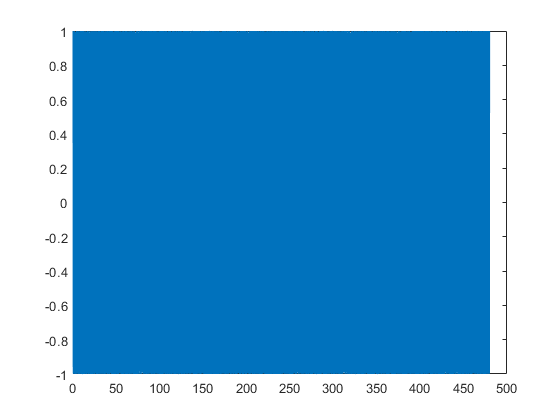

x = chirp(t,f0,t(end),f1);
sound(x, Fs)
figure(1)
plot(t, x)

                o Utilizar señales de audio

** - Operaciones adicionales:**

-  Sumar y multiplicar dos señales de audio

-  Reproducir de forma inversa el audio

-  Convertir una señal estereofónica (un solo canal) a monofónica (dos canales) y viceversa.

-  Conformar una señal estéreo a partir de dos señales monofónicas 

-  Ajustar el volumen del audio 

                o Amplitud constante 

                o Amplitud cambiando linealmente (creciente y decreciente) 

- Verificación y Cambio de la frecuencia de muestreo antes de realizar operaciones entre audios 

                o Opción 1: Usar dos funciones separadas de Matlab: Decimate y Interp 

                o Opción 2: Usar sola la función de Matlab: interp1 